%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2-layer SoS estimation and image reconstruction using DAS-IQ beamforming
% Supported modes: LdL/LLdLL (zero angle), TdT/TTdT (nonzero angle)
% Test: Steel pipe sample immersed in water, 20-mm standoff
% DW emission at three angles [-A,0,+A], frontwall crack(s)
% Author(s): Daler Rakhmatov (daler@ece.uvic.ca), Haoyun Chen (haoyunchen@
% uvic.ca), 24 May 2023
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% close all;
clear;
clc;

## Pipe sample parameters

% 303 stainless steel sample
DV_303_Sample.cL = 5640;                % longitudinal speed of sound [m/s]
DV_303_Sample.cT = 3120;                % transverse speed of sound [m/s]
DV_303_Sample.IR = 193.675*1e-3;        % pipe inner radius (front wall) [m]
DV_303_Sample.OR = 203.200*1e-3;        % pipe outer radius (back wall) [m]
DV_303_Sample.crack_present = true;     % crack presence (true/false)

## Load workspace variables and define imaged medium

rootID = 'E:\Dropbox\verasonics\256 Element\';

frameStep = 5;

pathID = 'data/';
fileID = 'DV14276-C_256_2V_PRF_600_5sec'; ID = 'DV14276'; frameStart = 142 + frameStep; frameEnd = 241 - frameStep; 
%fileID = 'DV15011-A_256_5V_PRF_600_4sec'; ID = 'DV15011'; frameStart = 120 + frameStep; frameEnd = 219 - frameStep;
%fileID = 'DV15013-A_256_5V_PRF_600_4sec'; ID = 'DV15013'; frameStart = 116 + frameStep; frameEnd = 215 - frameStep;
%fileID = 'DV15143A_2V_PRF_600_4sec'; ID = 'DV15143'; frameStart = 270 + frameStep; frameEnd = 369 - frameStep;
frameMid = round((frameStart+frameEnd)/2);
% fileID = 'DV15390-C_256_2V_PRF_600_5sec'; ID = 'DV15390'; frameMid = 238;

% load([rootID pathID fileID '.mat']);
load([pathID fileID '.mat']);
c2L = DV_303_Sample.cL;                 % nominal longitudinal SoS in steel
c2T = DV_303_Sample.cT;                 % nominal transverse SoS in steel
pipe_IR = DV_303_Sample.IR;
pipe_OR = DV_303_Sample.OR;
crack_present = DV_303_Sample.crack_present;

% ImgData - beamformed data by Verasonics (not used)
% P - Verasonics acquisition parameters (assumed speed of sound in m/s)
% RcvData - received RF channel data (num.samples*num.angles, num.channels, num.frames)
% Receive - Rx parameters (sampling rate in MHz, startSample:endSample per acquisition)
% Trans - Tx parameters (pulse freq. in MHz, num.elements, element spacing in mm)
% TX - TX delays (element firing delays per TX angle)


c0 = P.SOS;                             % assumed SoS in layer1 [m/s]
TXangles = P.Theta;                     % transmit angles [rad]
Na = numel(TXangles);                   % number of angles per frame

standoff = P.standoff*1e-3;             % nominal standoff [m]
layer2 = pipe_OR - pipe_IR;             % pipe thickness (layer2) [m]
zOffset = pipe_IR - standoff;           % transducer distance from virtual source

fc = Trans.frequency*1e6;               % transmit pulse frequency [Hz]
bw = fc*Trans.Bandwidth;                % bandwidth [Hz]

ds = Trans.spacingMm*1e-3;              % element spacing [m]
s_axis = Trans.ElementPos(:,1)*1e-3;
Ns = numel(s_axis);

Nt = Receive(1).endSample;              % number of samples per channel
fd = Receive(1).demodFrequency*1e6;     % demodulation frequency [Hz]
fs = Receive(1).decimSampleRate*1e6;    % sampling frequency [Hz]
dt = 1/fs;

t_axis = dt*(0:(Nt-1));                 % time axis [s]


TXdelays = zeros(Ns,Na);
for ia = 1:Na
    TXdelays(:,ia) = TX(ia).Delay/fc;   % TX delays [s]      
end

% virtual source configuration
origin = pipe_IR*sin(TXangles);
zv = origin.*sin(TXangles);
xv = -origin.*cos(TXangles);


absAngle_Lmode = deg2rad(5);        % L mode if within +/-5 deg angle (?)

t0 = 1/fc/2;                        % initial time offset (from Reza)

c1 = c0;                            % nominal SoS in layer1


% set SoS limits for estimation
c1_lim = [1400 1560];               % SoS in liquid (water)
c2L_lim = [5300 5900];              % longitudinal SoS in steel
c2T_lim = [2900 3300];              % transverse SoS in steel

## Prepare raw RF channel data for processing

Nf = size(RcvData{1},3);

muxInd = Trans.Connector;

channel_data = zeros(Nt,Ns,Na,Nf,'int16');

for frameNum = 1:Nf
    for ia = 1:Na
        channel_data(:,:,ia,frameNum) = ...
            squeeze(RcvData{1}((1:Nt)+(ia-1)*Nt,muxInd,frameNum));
    end
end

fprintf('\nChannel data size:\n[samples channels angles frames] = [%d %d %d %d]\n',Nt,Ns,Na,Nf);


Channel data size:
[samples channels angles frames] = [1792 256 3 1000]


## Define DAS beamforming grid

dx = 1e-4;
x_axis = (s_axis(1):dx:s_axis(end)).';  % lateral axis [m]
Nx = numel(x_axis);

dz = 1e-4;
z_axis = (0:dz:(standoff+3*layer2));    % depth axis [m]
Nz = numel(z_axis);

% lateral range
xMin = s_axis(1);
xMax = s_axis(end);
xIndRange = (1:Nx);

% axial range
zMin = z_axis(1);
zMax = z_axis(end);
zIndRange = (1:Nz);

span = standoff/4;                      % search span (+/-) [m]


% function parameters
params.ID = ID;
params.pipe_IR = pipe_IR;
params.pipe_OR = pipe_OR;
params.standoff = standoff;
params.layer2 = layer2;

params.Na = Na;
params.TXangles = TXangles;
params.TXdelays = TXdelays;

params.xv = xv;
params.zv = zv;
params.fc = fc;
params.fs = fs;

params.Ns = Ns;
params.ds = ds;
params.s_axis = s_axis ;

params.Nx = Nx;
params.dx = dx;
params.x_axis = x_axis;
params.xIndRange = xIndRange;
params.zIndRange = zIndRange;

params.Nt = Nt;
params.dt = dt;
params.t0 = t0;

params.Nz = Nz;
params.dz = dz;
params.z_axis = z_axis;
params.t_axis = t_axis;

params.zOffset = zOffset;
params.span = span;

## Analyze channel data first

NtFFT = pow2(nextpow2(Nt+1)+2);     % 4X extra padding
F0 = (0:NtFFT/2-1)/dt/NtFFT;        % positive temporal frequencies
% NOTE: NtFFT/2+1 bin discarded (to be filled with zeros during inversion)

% select data frame for SoS estimation
frameNum = frameMid;
RFdata = squeeze(channel_data(:,:,:,frameNum));

%-- estimate SoS in liquid using beamformed data

params.RFdata = RFdata;
IQdata = hilbert(RFdata).*exp(-1i*2*pi*fc*t_axis.');
params.IQdata = IQdata;

c1_step = 10;
c1_sweep = c1_lim(1):c1_step:c1_lim(2);
c1_est = f_sosEst1_IQ_int(params,c1_sweep);  %1480; 


Estimating speed of sound in liquid...


% use estimated SoS if within limits
if c1_lim(1) <= c1_est && c1_est <= c1_lim(2)
    c1 = c1_est;
end

fprintf('\nEstimated c1 = %d,  nominal value = %d\n',c1,c0);


Estimated c1 = 1470,  nominal value = 1480


params.c1 = c1;

%-- estimate transducer misalignment (using estimated SoS in layer1)

params.xErr0 = 0;               % initial lateral misalignment [m]
params.zErr0 = 0;               % initial axial misalignment [m]
thres = 1e6;                    % beamformed data energy threshold

[xErr,zErr,flag] = f_misalignEst_IQ(params,thres);


Estimating transducer misalignment...
Z error est. = 2.04 mm,  X error est. = -0.23 mm


% NOTE: flag = false --> [xErr,zErr] likely unreliable

params.zErr = zErr;
params.xErr = xErr;

layer1 = standoff + zErr;

%-- estimate transverse SoS in steel using nonzero-angle beamformed data
c2T_step = 10;
c2T_sweep = c2T_lim(1):c2T_step:c2T_lim(2);
c2T_est = f_sosEst2T_IQ_int(params,c2T_sweep);   %3120 


Estimating transverse speed of sound in steel...



% use estimated SoS if within limits
if c2T_lim(1) <= c2T_est && c2T_est <= c2T_lim(2)
    c2T = c2T_est;
end

fprintf('\nEstimated c2T = %d,  nominal value = %d\n',c2T,DV_303_Sample.cT);


Estimated c2T = 3100,  nominal value = 3120




%-- estimate longitudinal SoS in steel using zero-angle channel data
c2L_step = 10;
c2L_sweep = c2L_lim(1):c2L_step:c2L_lim(2);
c2L_est = f_sosEst2L_IQ_int(params,c2L_sweep);  %5640 


Estimating longitudinal speed of sound in steel...


% use estimated SoS if within limits
if c2L_lim(1) <= c2L_est && c2L_est <= c2L_lim(2)
    c2L = c2L_est;
end

fprintf('\nEstimated c2L = %d,  nominal value = %d\n',c2L,DV_303_Sample.cL);


Estimated c2L = 5710,  nominal value = 5640


## Process selected frames

% frameMid = round((frameStart+frameEnd)/2);

% for frameNum = frameMid%(frameStart:frameStep:frameEnd)

fprintf('\nFrame %d: Reconstruction started.\n',frameNum);


Frame 192: Reconstruction started.



% channel_RFdata = squeeze(channel_data(:,:,:,frameNum));
% %-- simulate compression/decompression during probe data transfer
% [RFdata_code,RFdata_pilot] = f_quantCompress_RF(channel_RFdata,partition,codebook);
% RFdata = f_quantDecompress_RF(RFdata_code,RFdata_pilot,codebook);
RFdata = squeeze(channel_data(:,:,:,frameNum));
params.RFdata = RFdata;

## Determine frontwall and backwall boundaries

frontDist = sqrt(pipe_IR^2 - (x_axis+xErr).^2) - pipe_IR + layer1;
backDist = sqrt(pipe_OR^2 - (x_axis+xErr).^2) - pipe_IR + layer1;

zAdj1 = frontDist - layer1;             % frontwall depth adjustment [m]
alpha1 = asin((x_axis+xErr)./pipe_IR);  % frontwall normal angle [rad]

zAdj2 = backDist - layer1 - layer2;     % backwall depth adjustment [m]
alpha2 = asin((x_axis+xErr)./pipe_OR);  % backwall normal angle [rad]

% mask of pipe region
patch_size = 0;
pipeMask = ones(Nz,Nx);
for ix = 1:Nx
    if (x_axis(ix) < xMin) || (x_axis(ix) > xMax)
        pipeMask(:,ix) = 0;
    else
        for iz = 1:Nz
            if (z_axis(iz) < frontDist(ix) - patch_size) || (z_axis(iz) > backDist(ix) + patch_size)
                pipeMask(iz,ix) = 0;
            end
        end
    end
end

% geometric/data specifications for later processing
geom.dx = dx;
geom.dz = dz;
geom.x_axis = x_axis(xIndRange);
geom.z_axis = z_axis(zIndRange);

geom.pipe_IR = pipe_IR;
geom.pipe_OR = pipe_OR;
geom.zOffset = zOffset;
geom.standoff = standoff;
geom.backDist = backDist(xIndRange);
geom.frontDist = frontDist(xIndRange);
geom.pipeMask = pipeMask(zIndRange,xIndRange);

geom.xErr = xErr;
geom.zErr = zErr;


data.c1 = c1;
data.c2L = c2L;
data.c2T = c2T;
data.lambda1 = c1/fc;                   % wavelength inside liquid [m]
data.lambda2L = c2L/fc;                 % L-wavelength inside pipe [m]
data.lambda2T = c2T/fc;                 % T-wavelength inside pipe [m]

data.TXangles = TXangles;               % nominal TX angles [rad]
data.theta1 = zeros(1,Na);
data.theta2 = zeros(1,Na);

## Calculate delays

NzBF = numel(zIndRange);
NxBF = numel(xIndRange);

BFdata_LdL = zeros(NzBF,NxBF);
BFdata_LLdLL = zeros(NzBF,NxBF);

BFdata_TdT_neg = zeros(NzBF,NxBF);
BFdata_TdT_pos = zeros(NzBF,NxBF);

BFdata_TTdT_neg = zeros(NzBF,NxBF);
BFdata_TTdT_pos = zeros(NzBF,NxBF);

BFdata_TdTT_neg = zeros(NzBF,NxBF);
BFdata_TdTT_pos = zeros(NzBF,NxBF);

BFdata_TTdTT_neg = zeros(NzBF,NxBF);
BFdata_TTdTT_pos = zeros(NzBF,NxBF);

% RX apodization window
%apodWinRX = chebwin(Ns,60).';
apodWinRX = ones(1,Ns);
params.apodWinRX = apodWinRX;



## Precompute RX delays

if (flag)
fprintf('Precomputing RX delays...\n');

delayRX_dL = Inf*ones(Nz,Nx,Ns);        % L-mode direct outgoing (RX) delay
delayRX_hL = Inf*ones(Nz,Nx,Ns);        % L-mode halfskip outgoing (RX) delay
delayRX_dT = Inf*ones(Nz,Nx,Ns);        % T-mode direct outgoing (RX) delay
delayRX_hT = Inf*ones(Nz,Nx,Ns);        % T-mode halfskip outgoing (RX) delay

for iz = zIndRange
    for ix = xIndRange

        if z_axis(iz) <= frontDist(ix)
            % inside layer1
            rx_delay1 = sqrt(z_axis(iz)^2 + (s_axis-x_axis(ix)).^2)/c1;
            delayRX_dL(iz,ix,:) = rx_delay1;
            delayRX_hL(iz,ix,:) = rx_delay1;
            delayRX_dT(iz,ix,:) = rx_delay1;
            delayRX_hT(iz,ix,:) = rx_delay1;

        else
            % outside layer1
            for ifw = 1:Nx
                a_fw = alpha1(ifw);
                x_fw = x_axis(ifw);
                z_fw = frontDist(ifw);

                % direct RX path
                delta_z = z_axis(iz) - z_fw;
                delta_x = x_fw - x_axis(ix);
                rx_path2_d = sqrt(delta_z^2 + delta_x^2);

                % direct RX delay
                delta_a = abs(atan(delta_x/delta_z));
                if delta_x >= 0
                    rx_angle2 = delta_a + a_fw;
                    % L-mode delay
                    rx_angle1 = asin(c1/c2L*sin(rx_angle2)) - a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw + z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_d/c2L + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_dL(iz,ix,x_sInd)
                        delayRX_dL(iz,ix,x_sInd) = cur_delay;
                    end
                    % T-mode delay
                    rx_angle1 = asin(c1/c2T*sin(rx_angle2)) - a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw + z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_d/c2T + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_dT(iz,ix,x_sInd)
                        delayRX_dT(iz,ix,x_sInd) = cur_delay;
                    end

                else
                    rx_angle2 = delta_a - a_fw;
                    % L-mode delay
                    rx_angle1 = asin(c1/c2L*sin(rx_angle2)) + a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw - z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_d/c2L + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_dL(iz,ix,x_sInd)
                        delayRX_dL(iz,ix,x_sInd) = cur_delay;
                    end
                    % T-mode delay
                    rx_angle1 = asin(c1/c2T*sin(rx_angle2)) + a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw - z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_d/c2T + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_dT(iz,ix,x_sInd)
                        delayRX_dT(iz,ix,x_sInd) = cur_delay;
                    end

                end

                % halfskip RX path
                if ifw >= ix, bwIndRange = (ix:ifw);
                else, bwIndRange = (ifw:ix);
                end
                % default: halfway point
                ibw = round((ix + ifw)/2);
                x_bw = x_axis(ibw);
                z_bw = backDist(ibw);
                rx_path2_h = sqrt((z_bw-z_axis(iz))^2 + (x_bw-x_axis(ix))^2)...
                    + sqrt((z_bw-z_fw)^2 + (x_fw-x_bw)^2);
                delta_z = z_bw - z_fw;
                delta_x = x_fw - x_bw;
                % scan backwall to improve default
                for ibw = bwIndRange
                    x_bw = x_axis(ibw);
                    z_bw = backDist(ibw);
                    h_path = sqrt((z_bw-z_axis(iz))^2 + (x_bw-x_axis(ix))^2)...
                        + sqrt((z_bw-z_fw)^2 + (x_fw-x_bw)^2);
                    if rx_path2_h > h_path
                        rx_path2_h = h_path;
                        delta_z = z_bw - z_fw;
                        delta_x = x_fw - x_bw;
                    end
                end

                % halfskip RX delay
                delta_a = abs(atan(delta_x/delta_z));
                if delta_x >= 0
                    rx_angle2 = delta_a + a_fw;
                    % L-mode delay
                    rx_angle1 = asin(c1/c2L*sin(rx_angle2)) - a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw + z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_h/c2L + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_hL(iz,ix,x_sInd)
                        delayRX_hL(iz,ix,x_sInd) = cur_delay;
                    end
                    % T-mode delay
                    rx_angle1 = asin(c1/c2T*sin(rx_angle2)) - a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw + z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_h/c2T + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_hT(iz,ix,x_sInd)
                        delayRX_hT(iz,ix,x_sInd) = cur_delay;
                    end
                else
                    rx_angle2 = delta_a - a_fw;
                    % L-mode delay
                    rx_angle1 = asin(c1/c2L*sin(rx_angle2)) + a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw - z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_h/c2L + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_hL(iz,ix,x_sInd)
                        delayRX_hL(iz,ix,x_sInd) = cur_delay;
                    end
                    % T-mode delay
                    rx_angle1 = asin(c1/c2T*sin(rx_angle2)) + a_fw;
                    rx_path1 = z_fw/cos(rx_angle1);
                    x_s = x_fw - z_fw*tan(rx_angle1);
                    x_sInd = round((x_s-s_axis(1))/ds) + 1;
                    cur_delay = rx_path2_h/c2T + rx_path1/c1;
                    if x_sInd >= 1 && x_sInd <= Ns && cur_delay < delayRX_hT(iz,ix,x_sInd)
                        delayRX_hT(iz,ix,x_sInd) = cur_delay;
                    end
                end

            end

        end

    end
end

delayRX_dL_interp = RX_interpolation(delayRX_dL, pipeMask);
delayRX_hL_interp = RX_interpolation(delayRX_hL, pipeMask);
delayRX_dT_interp = RX_interpolation(delayRX_dT, pipeMask);
delayRX_hT_interp = RX_interpolation(delayRX_hT, pipeMask);
delays.delayRX_dL = delayRX_dL_interp;
delays.delayRX_hL = delayRX_hL_interp;
delays.delayRX_dT = delayRX_dT_interp;
delays.delayRX_hT = delayRX_hT_interp;

Precomputing RX delays...


## Calculate TX delays and apply DAS beamforming

% Get complex IQdata
IQdata = hilbert(RFdata).*exp(-1i*2*pi*fc*t_axis.');
params.IQdata = IQdata;
data = beamforming(params, data, geom, delays, true);

end %-- end (flag)

Illegal use of reserved keyword "end".


TX angle = -20.0 deg
Calculating TX delays...


Unrecognized function or variable 'xerr'.

Error in beamforming (line 147)
                B = 2 * (ta^2*xerr - beta);
                ^^^^^^^^^^^^^^^^^^^^^^^^^^^

fprintf('\nReconstruction completed.\n');

## Save workspace variables for later processing

%fprintf('\nSaving data...\n');

BFdata_LdL = data.LdL;                  % zero-angle LdL data
BFdata_LLdLL = data.LLdLL;              % zero-angle LLdLL data
BFdata_TdT_neg = data.TdT_neg;          % negative-angle TdT data
BFdata_TdT_pos = data.TdT_pos;          % positive-angle TdT data
BFdata_TdTT_neg = data.TdTT_neg;        % negative-angle TdTT data
BFdata_TdTT_pos = data.TdTT_pos;        % positive-angle TdTT data
BFdata_TTdT_neg = data.TTdT_neg;        % negative-angle TTdT data
BFdata_TTdT_pos = data.TTdT_pos;        % positive-angle TTdT data
BFdata_TTdTT_neg = data.TTdTT_neg;      % negative-angle TTdTT data
BFdata_TTdTT_pos = data.TTdTT_pos;      % positive-angle TTdTT data



## Display and record beamformed data for middle frame

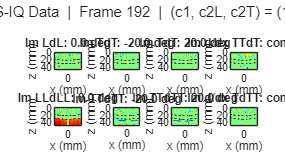

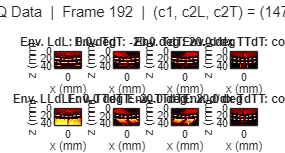

matFile = ['.\' sprintf('das256_[%s]_frame%d.mat',ID,frameNum)];

%save(matFile,'geom','data');
if frameNum == frameMid

    crange = max(abs(BFdata_LdL(:)));

    %--------------------------------------------------------

    figure('Position',[0,50,1300,700]);
    sgtitle(['Imaginary Part of DAS-IQ Data  |  ' ...
        sprintf('Frame %d  |  (c1, c2L, c2T) = (%d, %d, %d) m/s\n', frameNum,c1,c2L,c2T)]);

    % LdL mode - zero angle
    ax = subplot(2,4,1);
    img = imag(BFdata_LdL);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im LdL: %.1f deg',rad2deg(TXangles(2))));

    % LLdLL mode - zero angle
    ax = subplot(2,4,5);
    img = imag(BFdata_LLdLL);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im LLdLL: %.1f deg',rad2deg(TXangles(2))));

    % TdT mode - negative angle
    ax = subplot(2,4,2);
    img = imag(BFdata_TdT_neg);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im TdT: %.1f deg',rad2deg(TXangles(1))));

    % TdT mode - positive angle
    ax = subplot(2,4,3);
    img = imag(BFdata_TdT_pos);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im TdT: %.1f deg',rad2deg(TXangles(3))));

    % TTdTT mode - negative angle
    ax = subplot(2,4,6);
    img = imag(BFdata_TTdTT_neg);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im TTdTT: %.1f deg',rad2deg(TXangles(1))));

    % TTdTT mode - positive angle
    ax = subplot(2,4,7);
    img = imag(BFdata_TTdTT_pos);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange crange]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im TTdTT: %.1f deg',rad2deg(TXangles(3))));
    
    crange_g = max(max((imag(gradient(BFdata_TTdT_pos)))));
    %crange_g = 30;
    % TTdT mode - compounded gradient
    ax = subplot(2,4,4);
    img = imag(gradient(BFdata_TTdT_pos) + gradient(BFdata_TTdT_neg))/2;
    %img = gradient(imag(BFdata_TTdT_pos) + imag(BFdata_TTdT_neg))/2;
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange_g crange_g]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im d/dx TTdT: comp.'));

    % TdTT mode - compounded gradient
    ax = subplot(2,4,8);
    img = imag(gradient(BFdata_TdTT_pos) + gradient(BFdata_TdTT_neg))/2;
    %img = gradient(imag(BFdata_TdTT_pos) + imag(BFdata_TdTT_neg))/2;
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,img);
    caxis([-crange_g crange_g]/2); colormap(ax,"jet"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'k:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'k:','LineWidth',1);
        hold off;
    end
    title(sprintf('Im d/dx TdTT: comp.'));

    %saveas(gcf,sprintf('images/das256_[%s]_frame%d_Im.fig',ID,frameNum));

    %--------------------------------------------------------

    figure('Position',[0,50,1300,700]);
    sgtitle(['Envelope of DAS-IQ Data  |  ' ...
        sprintf('Frame %d  |  (c1, c2L, c2T) = (%d, %d, %d) m/s\n', frameNum,c1,c2L,c2T)]);

    % LdL mode - zero angle
    ax = subplot(2,4,1);
    env = abs(BFdata_LdL);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. LdL: %.1f deg',rad2deg(TXangles(2))));

    % LLdLL mode - zero angle
    ax = subplot(2,4,5);
    env = abs(BFdata_LLdLL);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. LLdLL: %.1f deg',rad2deg(TXangles(2))));

    % TdT mode - negative angle
    ax = subplot(2,4,2);
    env = abs(BFdata_TdT_neg);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. TdT: %.1f deg',rad2deg(TXangles(1))));  

    % TdT mode - positive angle
    ax = subplot(2,4,3);
    env = abs(BFdata_TdT_pos);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. TdT: %.1f deg',rad2deg(TXangles(3))));  

    % TTdTT mode - negative angle
    ax = subplot(2,4,6);
    env = abs(BFdata_TTdTT_neg);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. TTdTT: %.1f deg',rad2deg(TXangles(1))));

    % TTdTT mode - positive angle
    ax = subplot(2,4,7);
    env = abs(BFdata_TTdTT_pos);
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. TTdTT: %.1f deg',rad2deg(TXangles(3))));
    
    crange_g = max(max((abs(gradient(BFdata_TTdT_pos)))));
    %crange_g = 30;
    % TTdT mode - compounded gradient
    ax = subplot(2,4,4);
    env = abs(gradient(BFdata_TTdT_pos) + gradient(BFdata_TTdT_neg))/2;
    %env = gradient(abs(BFdata_TTdT_pos) + abs(BFdata_TTdT_neg))/2;
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange_g]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. d/dx TTdT: comp.'));

    % TdTT mode - compounded gradient
    ax = subplot(2,4,8);
    env = abs(gradient(BFdata_TdTT_pos) + gradient(BFdata_TdTT_neg))/2;
    %env = gradient(abs(BFdata_TdTT_pos) + abs(BFdata_TdTT_neg))/2;
    imagesc(x_axis(xIndRange)*1e3,z_axis(zIndRange)*1e3,env);
    caxis([0 crange_g]/2); colormap(ax,"hot"); axis image; %colorbar;
    xlabel('x (mm)'); ylabel('z (mm)');
    if (flag)
        hold on;
        plot(x_axis(xIndRange)*1e3,frontDist(xIndRange)*1e3,'w:','LineWidth',1);
        plot(x_axis(xIndRange)*1e3,backDist(xIndRange)*1e3,'w:','LineWidth',1);
        hold off;
    end
    title(sprintf('Env. d/dx TdTT: comp.'));

    
    %saveas(gcf,sprintf('images/das256_[%s]_frame%d_Env.fig',ID,frameNum));

    %--------------------------------------------------------

end





fprintf('\nDone.\n\n');


Done.

